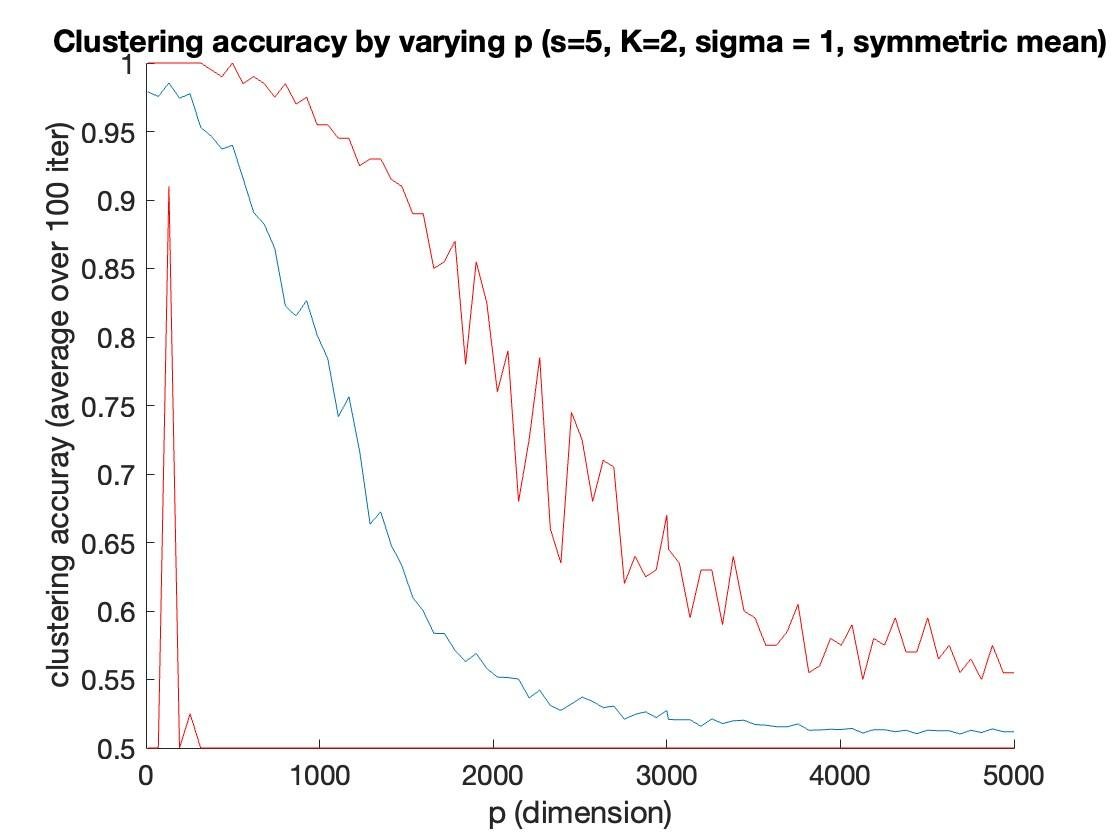

iterative thresholding

1. run  SDP k-means. re-arrange the rows to get $X_{{\mathcal{G}}_1}$and $X_{{\mathcal{G}}_2}$.

2. Calculate group sample means:

                
$$\bar{X}_{{\mathcal{G}}1} := {n{{\mathcal{G}}_1}}^{-1} 1^\top X{{\mathcal{G}}_1}
\\
\bar{X}_{{\mathcal{G}}_2} := {n{{\mathcal{G}}_2}}^{-1} 1^\top X{{\mathcal{G}}_2}$$


3. guess the non-zero entries: make a zero-one vectors by thresholding each element of the group sample mean by


$$ c_1 = \sigma \sqrt{ \frac{2 \log p}{{n_{{\mathcal{G}}1}}}}, \quad c_2 = \sigma \sqrt{\frac{2 \log p}{{n_{{\mathcal{G}}_2}}}} $$


4. Apply thresholding to the data matrix (not affinity matrix)

5. Run SDP k-means to the thresholded data

6. iterate 2-5.

n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 4; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);

p_start = 10;
p_end = 15000;
n_grid = 20;
p_vec =  [round(linspace(p_start, p_end, n_grid))];
n_rep = 40;

n_pararell = 10;
n_p_chunk = n_grid/n_pararell;
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end


parpool('Processes')

tic
% parallel for loop
parfor w = 1 : n_pararell
%
    for i = 1:length(p_vec_chunk{w})
    p = p_vec_chunk{w}(i)
    fprintf("p=%i",p)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
        x_now = x;
        A_now = (x_now * x_now')/ n;
        Z_now = kmeans_sdp(A_now, K);     
        cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);
        cluster_acc_before_thres = max( ...
            mean(cluster_true ==  cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            );
        %fprintf("p = %i, acc before thres: %f", p, cluster_acc_before_thres);
    
        % iterate
 
        clustering_acc_mat_chunk{w}(j, i) = iterative_kmeans(x, sigma, K, p, n_iter, rounding, n, cluster_true);
    end
end
end

p=11055  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 

toc

Elapsed time is 3918.112351 seconds.


clustering_acc_mat = [];
for i = 1:n_pararell
    clustering_acc_mat = [clustering_acc_mat, clustering_acc_mat_chunk{i}];
end

x_axis_val = p_vec;                     
y_axis_val = mean(clustering_acc_mat,1);
y_axis_max = max(clustering_acc_mat);
y_axis_min = min(clustering_acc_mat);

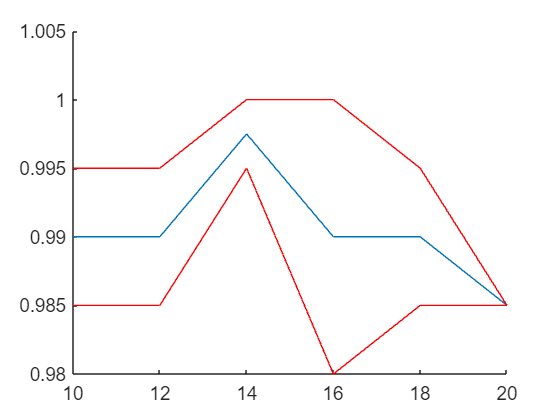


figure;
         

hold on
plot(x_axis_val,y_axis_val)
plot(x_axis_val,y_axis_max,'red')
plot(x_axis_val,y_axis_min,'red')
hold off